# Personalization & Nudging

## How to use this live script

As usual, in this executable notebook (Live Editor) you have a logical track of the work, not a full pipeline but a trace, with working code snippets, some (non-binding) method suggestions, etc. (When it comes to data modeling, there is almost never a "one size fits all", thus you can take various ways to solve the problem.)

So feel free to take this code as a draft, change it, even significantly, following your modeling vision. Feel free to explore data and methods and gain experience (yes, even getting it wrong and getting results you don't like - it's quite normal in real applications). You will find some "*HINTS*": they are just suggestions for you. Remember: experimenting with data - that's the purpose of this Machine Learning Lab.

We will use a dataset called "NudgingContents.mat".

## Goal: personalized nudging contents

We have to convince clients to make investments that suit them, and we have to find the best persuasion technique. That is, we want to understand what kind of "nudging" works best for each type of client, represented by Financial Marketing Personas (see the class on "Segmenting Clients" and the class on "Recommendation Systems").

We will use Machine Learning techniques for *incremental learning*, or *online learning*, or *continuous learning*. 

*Online learning*, is a branch of Machine Learning that involves processing incoming data from a data stream, often continuously and in real time.

Incremental learning algorithms are typically lean, flexible, efficient, and above all adaptive, similar to Stochastic Gradient Descent in some way. Anyway, see: [https://it.mathworks.com/help/stats/incremental-learning-overview.html](https://it.mathworks.com/help/stats/incremental-learning-overview.html).

I should mention that one interesting effect of online learning algorithms is that they can really adapt to changing user preferences: the model will just slowly adapt your parameters to whatever your latest pool of users looks like.

Please note: the problem can be formulated as a "standard" Machine Learning problem. So you could use the usual approach: you collect a lot of data, there are responses Y and features X, and you can use any classifier, such as a neural network, or a random forest, or whatever, you do standard train/CV/test, doing hyperparameterds fine-tuning in CV and so on, as we did in the Recommendation Sistem class - and I encourage you to compare the two approaches, in terms of results... it might be interesting.

#### Upload data

close all
clc
path = '/Users/raffaelezenti/Dropbox (virtualb)/RaffaeleZenti/MyMatlab/Laboratorio_Politecnico_Milano/NudgingContents.mat';
load(path)

We have three different nudging contents (they can be much more), that is  **Storytelling**, **Peer Comparison**, **Framing**, and a recorded stream of clicks for **8 different customer personas**, based on 3 boolean (after encoding) features, so we have 2^3=8 personas.

Our sample:

- y_ST: boolean responses about nudging with "**Storytelling**", 1 if the user clicked on the call-to-action, 0 otherwise;  nObsST x 1;

- X_ST: [persona {1, 2,..., 8}   age {0 if <42, 1 if >= 42 }  gender {0 = F, 1 = M}  education {0 = low, 1 = high};  nObsST x 4;

- y_PC: boolean responses about nudging with "**Peer Comparison**", 1 if the user clicked on the call-to-action, 0 otherwise;  nObsPC x 1;

- X_PC: [persona {1, 2,..., 8}   age {0 if <42, 1 if >= 42 }  gender {0 = F, 1 = M}  education {0 = low, 1 = high}; nObsPC x 4;

- y_FR: boolean responses about nudging with "**Framing**", 1 if the user clicked on the call-to-action, 0 otherwise;  nObsFR x 1;

- X_FR: [persona {1, 2,..., 8}   age {0 if <42, 1 if >= 42 }  gender {0 = F, 1 = M}  education {0 = low, 1 = high}; nObsFR x 4;

- Personas: a matrix with the encoding of the personas - ie a mathematical description of each personas in terms of 0, 1...

Note that we have three different number of examples, nObsST, nObsPC, nObsFR, because of the underlying data collection design, which is obviously randomized.

So the feature vectors X_ST, X_PC, X_FR contain both the summary variable (the type of marketing person, a number from 1 to 8), and the detail in terms of age, gender and education: let's separate this data.

You can alternatively use the personas as a synthetic indicator of the human typology of each individual, or the underlying variables - age, gender, education.

% Storytelling
Personas_ST = X_ST(:,1); % personas synthetic index
Features_ST = X_ST(:,2:end); % personas drill-down

% Peer comparison
Personas_PC = X_PC(:,1); % personas synthetic index
Features_PC = X_PC(:,2:end); % personas drill-down

% Framing
Personas_FR = X_FR(:,1); % personas synthetic index
Features_FR = X_FR(:,2:end); % personas drill-down

PersonasValues = unique(Personas_ST) % check the values

PersonasValues =      1
     2
     3
     4
     5
     6
     7
     8


Personas mathematical description:

- Rows corresponds to different personas {1, 2,..., 8};

- Columns corresponds to age {0 <42, 1 >= 42 }  gender {0 = F, 1 = M}  education {0 = low, 1 = high}.

Personas

Personas =      0     0     0
     0     1     0
     0     0     1
     0     1     1
     1     0     0
     1     1     0
     1     0     1
     1     1     1


## Warm up on the Beta distribution and Bayes Theorem

### Beta distribution

I'm sure you know it well, but better review it quickly:

- It is a continuous distribution, its domain is [0, 1]; it assumes a great variety of forms;

- Parameterized by two shape parameters, that is, a, b;

- Computationally very tractable;

- Therefore it is great for modeling probabilities, or frequencies, or propensities, or beliefs.

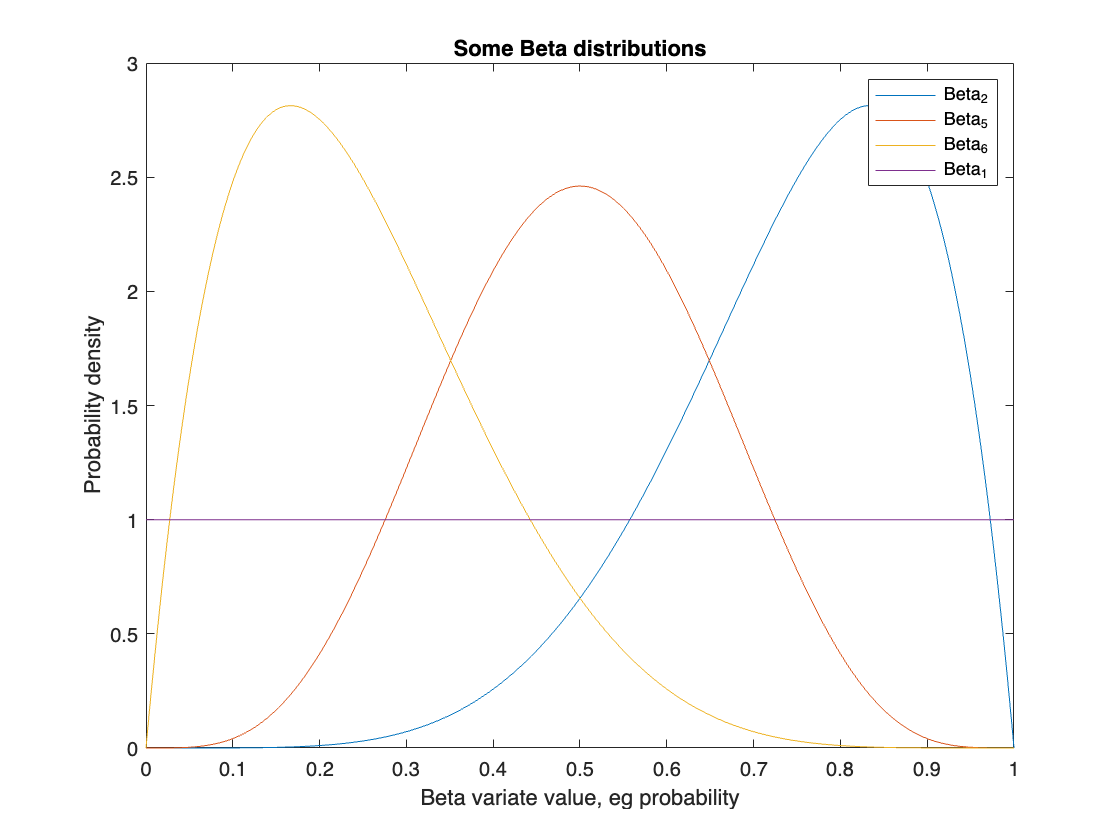

x = 0:0.001:1; % domain [0, 1]

Beta_1_1 = betapdf(x,1,1);
Beta_2_6 = betapdf(x,2,6);
Beta_6_2 = betapdf(x,6,2);
Beta_5_5 = betapdf(x,5,5);
figure
plot(x,Beta_6_2,'DisplayName','Beta_6_,_2');hold on;plot(x,Beta_5_5,'DisplayName','Beta_5_,_5');...
    plot(x,Beta_2_6,'DisplayName','Beta_2_,_6');plot(x,Beta_1_1,'DisplayName','Beta_1_,_1');hold off;
xlabel('Beta variate value, eg probability')
ylabel('Probability density')
title('Some Beta distributions')
legend

### The Bayesian Beta-Binomial model in short

We have to model a probability of clicking on an banner.

According to **Bayes Theorem**:

#### 
$$\textrm{Prob}\left(\textrm{click}|\textrm{data}\right)\propto\textrm{Prob}\left(\textrm{data}|\textrm{click}\right)\cdot \textrm{Prob}\left(\textrm{click}\right)$$


or

#### 
$$\textrm{Posterior}\propto\textrm{Likelihood}\cdot \textrm{Prior}$$


Let's workout the concrete solution - stay with me, it is really simple.

#### Prior = Prob(Click)

Let's assume we don't know anything, just that is in [0, 1]. So we use an uninformative prior, a Beta(a=1, b=1), which is FLAT, to model our uncertainty.

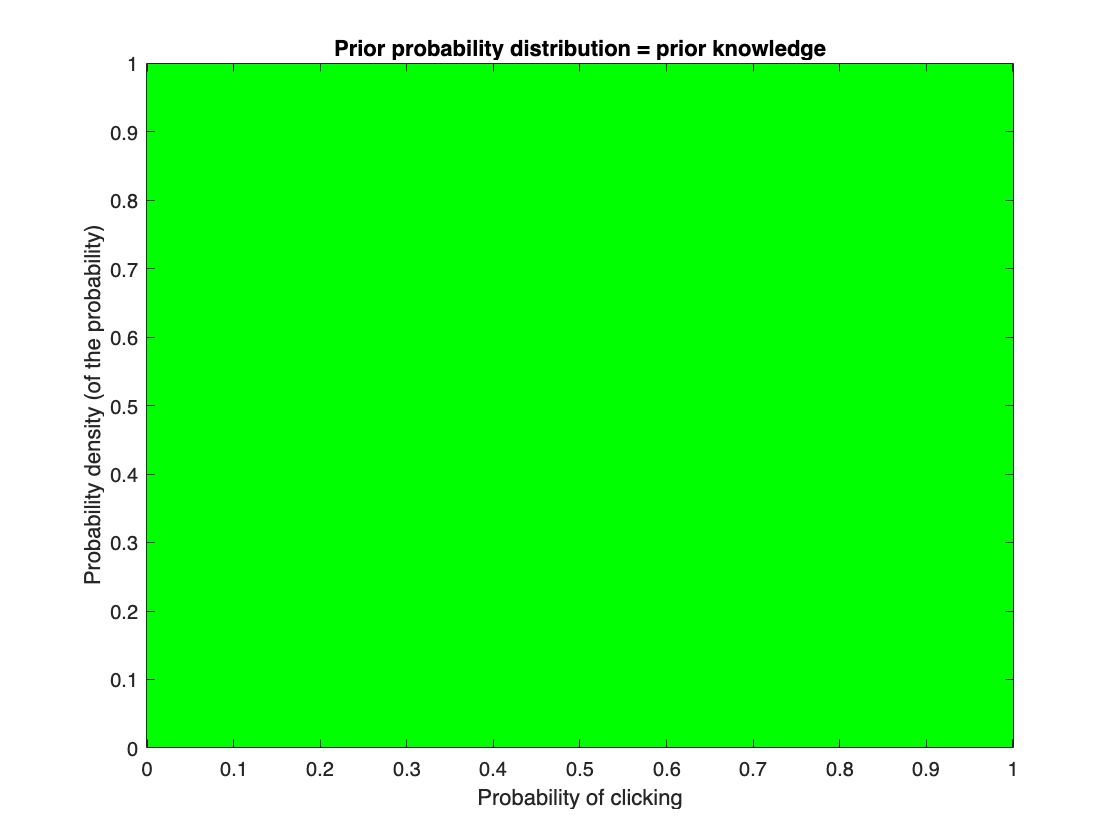

x = 0:0.001:1; % domain [0, 1]
aPrior = 1;
bPrior = 1;
prior = betapdf(x, aPrior, bPrior);
figure
bar(x,prior,'DisplayName','y', 'EdgeColor','g')
xlabel('Probability of clicking')
ylabel('Probability density (of the probability)')
title('Prior probability distribution = prior knowledge')

#### Likelihood

The random process click / don't click is clearly Binomial. So the likelihood is Binomial.

But p = probability parameter in the Binomial distribution follows a Beta distribution, so, to make a long story short (but see the paper in the course material), for our practical purposes, the likelihood is a Beta distribution...

Now, we collect some data about clicking: say, some 3 users clicked on the banner, some other 9 did'n t click on the banner.

So our likelihood is a Beta(a=3, b=9), that is:

- a = #positive cases = 3;

- b =#negative cases = 9.

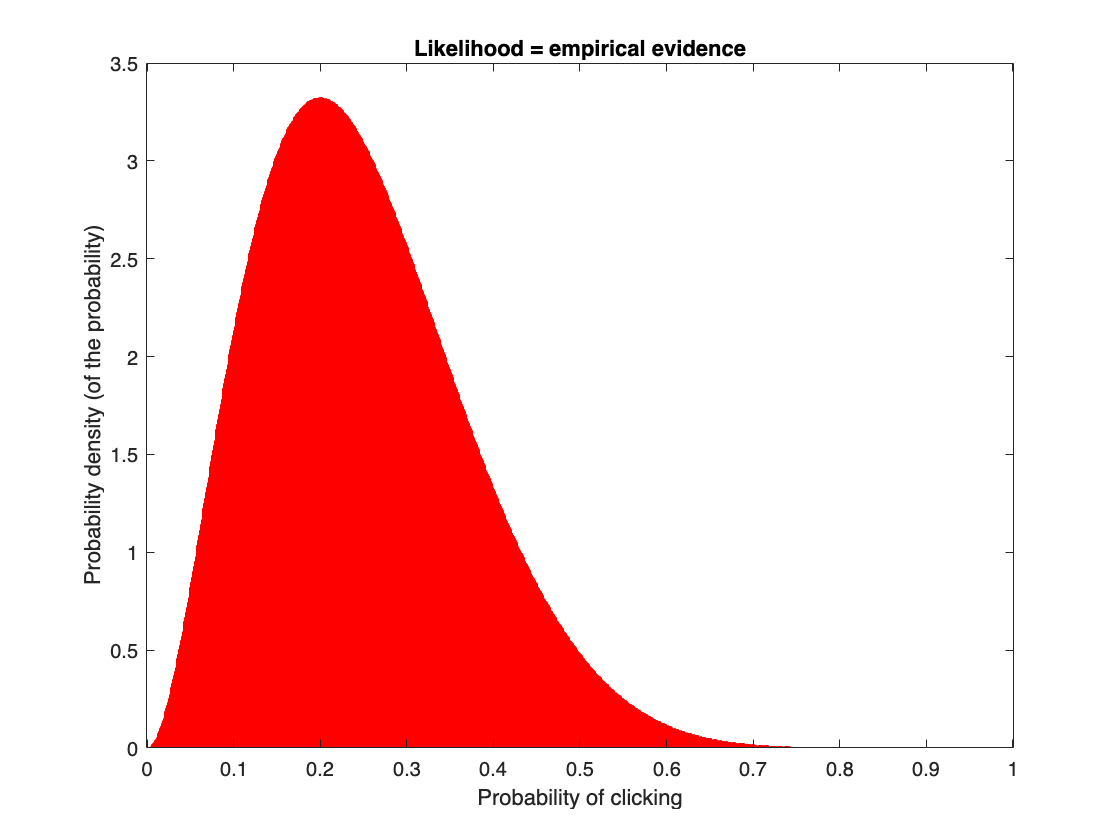

x = 0:0.001:1; % domain [0, 1]
aLikelihood = 3;
bLikelihood = 9;
likelihood = betapdf(x, aLikelihood, bLikelihood);
figure
bar(x,likelihood,'DisplayName','y', 'EdgeColor','red')
xlabel('Probability of clicking')
ylabel('Probability density (of the probability)')
title('Likelihood = empirical evidence')

#### Posterior

We have to do the product: likelihood x prior.

In general, this kind of product can be tough - it's problem #1 in Bayesian Statistics - but not today, not with this model: we are dealing we a conjugate prior for our likelihood, see: [https://en.wikipedia.org/wiki/Conjugate_prior](https://en.wikipedia.org/wiki/Conjugate_prior). 

Likelihood is Beta, prior is Beta. This fact leads to an analytically tractable compound distribution: it is really simple, we just have to add the exponents.

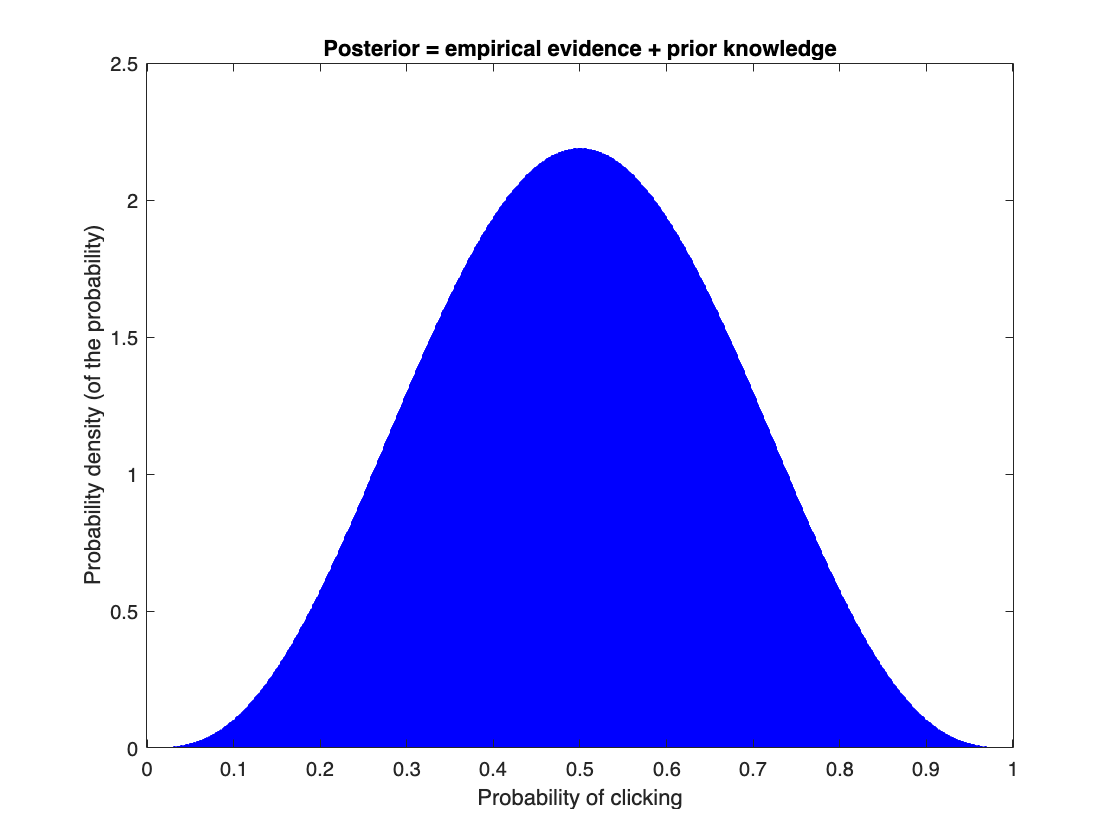

x = 0:0.001:1; % domain [0, 1]
aPosterior = aLikelihood + aPrior;
bPosterior = bLikelihood + bPrior;
posterior = betapdf(x, aPosterior, aPosterior);
figure
bar(x,posterior,'DisplayName','y', 'EdgeColor','blue')
xlabel('Probability of clicking')
ylabel('Probability density (of the probability)')
title('Posterior = empirical evidence + prior knowledge')

***HINT***: try different parameters a, b for the prior, and see the effet on the posterior.

## Bayesian Beta-Binomial model at work

This is the plan:

- Use a simple online learning model, the Beta-Binomial model;

- For each persona estimate Prob(click | nudging i), where i = 1,2,3, because we have three nudging contents;

- For each persona pick the nudging content with the highest probability to convince the customer: that is,

                            
$$\textrm{Argmax}\left\lbrace \textrm{Prob}\left(\textrm{click}\;|\;{\textrm{nudging}}_i \right)\right\rbrace$$
 

- We have a Cold-start - we start from scratch, from zero information.

#### Storytelling

We are not online, this is a Machine Learning class... so we try to recreate the "live conditions":

- We simulate the original data stream of responses;

- We have a "cold start", ie we begin with no data at all;

- We process chunks of length Chunk = batch = 50 observations at a time;

- We fit the incremental Bayesian Beta-Binomial model to the training data;

- At every instant we have the posterior probability distribution for each marketing persona.

Chunk = 50;
numPersonas = length(PersonasValues);
aBetaPosterior = cell(1, numPersonas); % cell arrays store vectors of different lengths
bBetaPosterior = cell(1, numPersonas);
meanProb = cell(1, numPersonas);
modeProb = cell(1, numPersonas);

for i = 1:numPersonas
    y = y_ST(Personas_ST == i); % responses for a given marketing persona
    n = length(y);
    nChunk = floor(n/Chunk);
    
    % Priors & preallocation
    aBetaPrior = 1;
    bBetaPrior = 1;
    aBetaPosterior_j = zeros(nChunk, 1); % store pdf parameter "a"
    bBetaPosterior_j = zeros(nChunk, 1); % store pdf parameter "b"
    meanProb_j = zeros(nChunk, 1); % store running mean
    modeProb_j = zeros(nChunk, 1); % store running mode

    % Incremental learning
    for j = 1:nChunk
        ibegin = min(n, nChunk*(j - 1) + 1);
        iend = min(n, nChunk*j);
        idx = ibegin:iend;
        % fit and update metrics
        nTot = length(y(idx)); % chunk-sample size
        nClick = sum(y(idx)); % number of positive responses
        aBetaPosterior_j(j) = aBetaPrior + nClick; % parameter #1 update
        bBetaPosterior_j(j) = bBetaPrior + (nTot - nClick); % parameter #2 update
        meanProb_j(j) = aBetaPosterior_j(j)/(aBetaPosterior_j(j) + bBetaPosterior_j(j)); % posterior mean
        modeProb_j(j) = (aBetaPosterior_j(j) - 1)/(aBetaPosterior_j(j) + bBetaPosterior_j(j) - 2); % posterior mode
        aBetaPrior = aBetaPosterior_j(j); % "Yesterday's posterior is today's prior"
        bBetaPrior = bBetaPosterior_j(j); % "Yesterday's posterior is today's prior"
    end
    
    aBetaPosterior{1, i} = aBetaPosterior_j;
    bBetaPosterior{1, i} = bBetaPosterior_j;
    meanProb{1, i} = meanProb_j;
    modeProb{1, i} = modeProb_j;
end

% Store the last, updated values
ST_LastProb = zeros(1, numPersonas);
for i = 1:numPersonas
    ST_LastProb(i) = meanProb{1, i}(end);
end

Let's try to better understand the learning process of the Bayesian model, starting from the mean and the mode for each marketing persona.

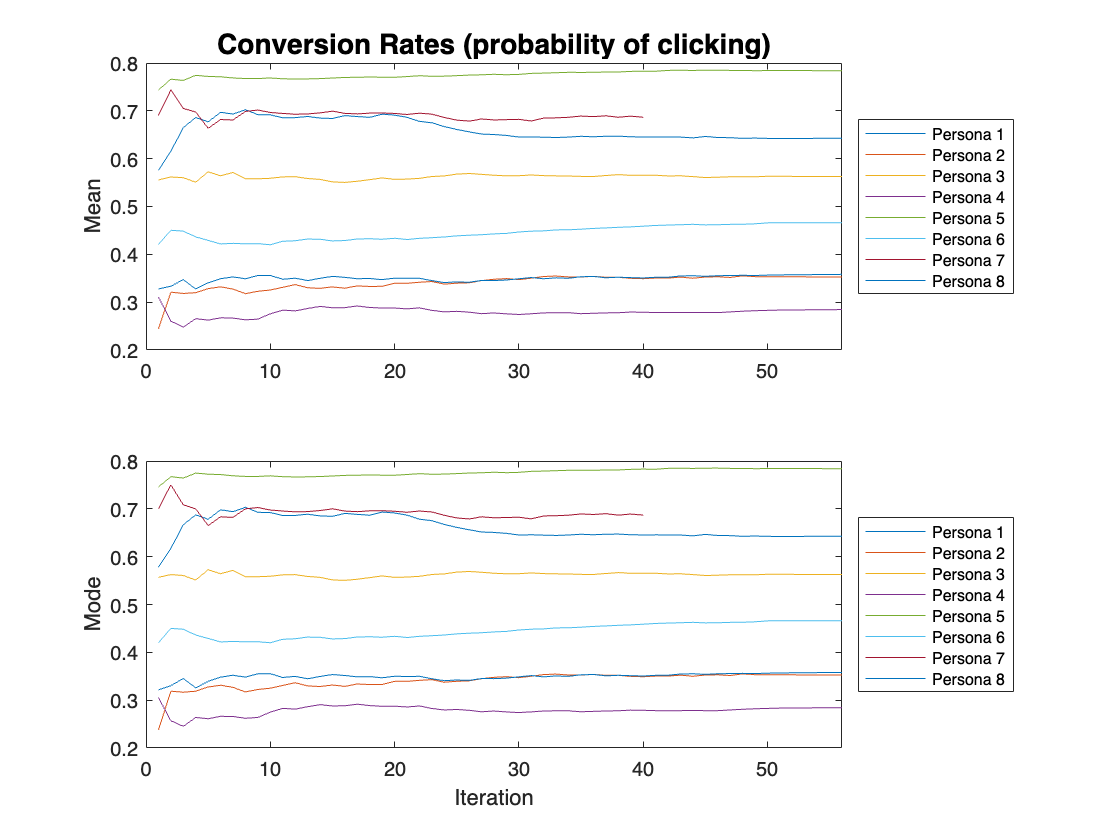

figure;
title('Storytelling: conversion Rates (probability of clicking)', "FontSize",16)
subplot(2,1,1)
for i = 1:numPersonas
    plot(meanProb{1, i})
    hold on
end
hold off
ylabel('Mean')
xlim([0 nChunk])
legend({'Persona 1','Persona 2','Persona 3','Persona 4','Persona 5','Persona 6','Persona 7','Persona 8'},...
    'location', 'eastoutside','NumColumns',1, 'FontSize',8)
title('Conversion Rates (probability of clicking)', "FontSize",14)

subplot(2,1,2)
for i = 1:numPersonas
    plot(modeProb{1, i})
    hold on
end
hold off
xlim([0 nChunk]);
legend({'Persona 1','Persona 2','Persona 3','Persona 4','Persona 5','Persona 6','Persona 7','Persona 8'},...
    'location', 'eastoutside','NumColumns',1, 'FontSize',8)
ylabel('Mode')
xlabel('Iteration')

Now let's take a look at the evolution of posterior distribution over time - we choose a marketing persona among {1, 2,..., 8} .

idxPersona = 2; % choose a marketing persona {1, 2,..., 8} 

Then we plot the posteriors at each step of the Bayesian learning process (Bayesian update).

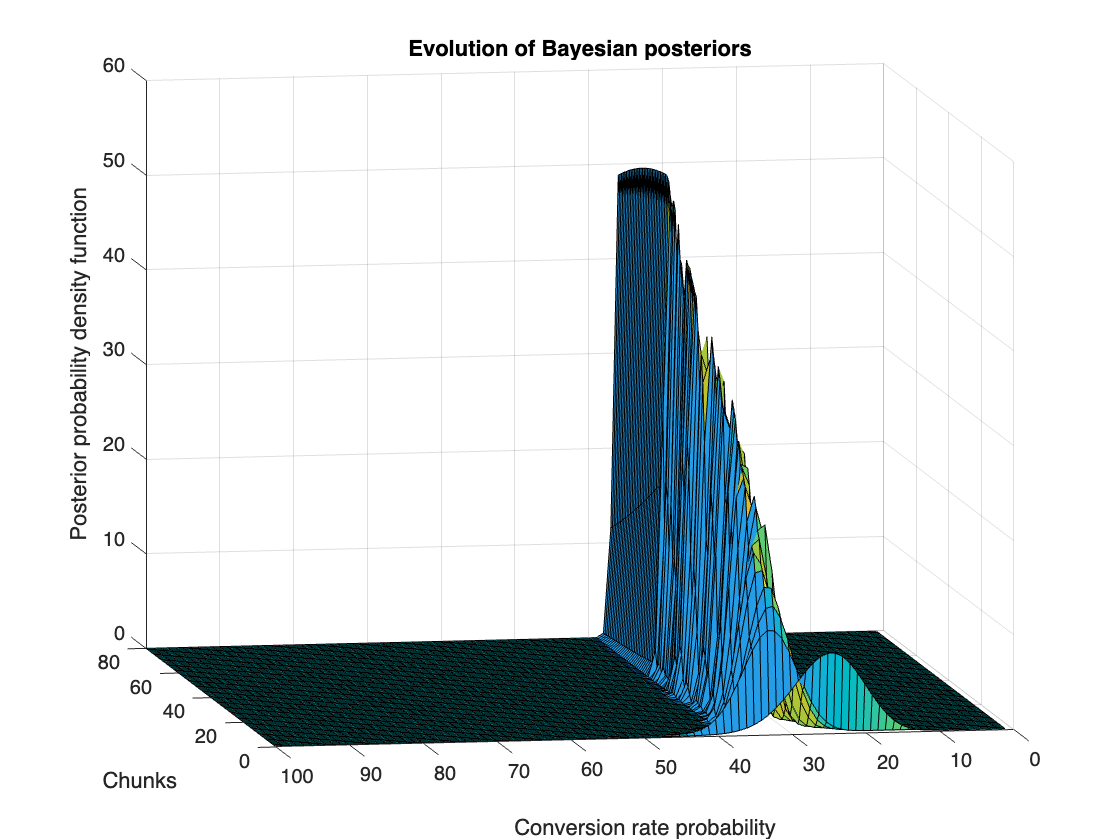

x = linspace(0,1,100)';
a = aBetaPosterior{1, idxPersona};
b = bBetaPosterior{1, idxPersona};
evalPoints = length(a);
Posteriors = zeros(100, evalPoints);
Posteriors(:,1) = betapdf(x,aBetaPrior,bBetaPrior);
for i = 1:evalPoints
    Posteriors(:,i) = betapdf(x,a(i),b(i));
end

figure
surfl(Posteriors)
title('Evolution of Bayesian posteriors')
view(-100,10)
xlabel('Chunks')
ylabel('Conversion rate probability')
zlabel('Posterior probability density function')

#### Peer Comparison

Same story...

Chunk = 50;
numPersonas = length(PersonasValues);
aBetaPosterior = cell(1, numPersonas); % cell arrays store vectors of different lengths
bBetaPosterior = cell(1, numPersonas);
meanProb = cell(1, numPersonas);
modeProb = cell(1, numPersonas);

for i = 1:numPersonas
    y = y_PC(Personas_PC == i); % responses for a given marketing persona
    n = length(y);
    nChunk = floor(n/Chunk);
    
    % Priors & preallocation
    aBetaPrior = 1;
    bBetaPrior = 1;
    aBetaPosterior_j = zeros(nChunk, 1); % store pdf parameter "a"
    bBetaPosterior_j = zeros(nChunk, 1); % store pdf parameter "b"
    meanProb_j = zeros(nChunk, 1); % store running mean
    modeProb_j = zeros(nChunk, 1); % store running mode

    % Incremental learning
    for j = 1:nChunk
        ibegin = min(n, nChunk*(j - 1) + 1);
        iend = min(n, nChunk*j);
        idx = ibegin:iend;
        % fit and update metrics
        nTot = length(y(idx)); % chunk-sample size
        nClick = sum(y(idx)); % number of positive responses
        aBetaPosterior_j(j) = aBetaPrior + nClick; % parameter #1 update
        bBetaPosterior_j(j) = bBetaPrior + (nTot - nClick); % parameter #2 update
        meanProb_j(j) = aBetaPosterior_j(j)/(aBetaPosterior_j(j) + bBetaPosterior_j(j)); % posterior mean
        modeProb_j(j) = (aBetaPosterior_j(j) - 1)/(aBetaPosterior_j(j) + bBetaPosterior_j(j) - 2); % posterior mode
        aBetaPrior = aBetaPosterior_j(j); % "Yesterday's posterior is today's prior"
        bBetaPrior = bBetaPosterior_j(j); % "Yesterday's posterior is today's prior"
    end
    
    aBetaPosterior{1, i} = aBetaPosterior_j;
    bBetaPosterior{1, i} = bBetaPosterior_j;
    meanProb{1, i} = meanProb_j;
    modeProb{1, i} = modeProb_j;
end

% Store the last, updated values
PC_LastProb = zeros(1, numPersonas);
for i = 1:numPersonas
    PC_LastProb(i) = meanProb{1, i}(end);
end

#### Framing

All over again, same story for framing...

Chunk = 50;
numPersonas = length(PersonasValues);
aBetaPosterior = cell(1, numPersonas); % cell arrays store vectors of different lengths
bBetaPosterior = cell(1, numPersonas);
meanProb = cell(1, numPersonas);
modeProb = cell(1, numPersonas);

for i = 1:numPersonas
    y = y_FR(Personas_FR == i); % responses for a given marketing persona
    n = length(y);
    nChunk = floor(n/Chunk);
    
    % Priors & preallocation
    aBetaPrior = 1;
    bBetaPrior = 1;
    aBetaPosterior_j = zeros(nChunk, 1); % store pdf parameter "a"
    bBetaPosterior_j = zeros(nChunk, 1); % store pdf parameter "b"
    meanProb_j = zeros(nChunk, 1); % store running mean
    modeProb_j = zeros(nChunk, 1); % store running mode

    % Incremental learning
    for j = 1:nChunk
        ibegin = min(n, nChunk*(j - 1) + 1);
        iend = min(n, nChunk*j);
        idx = ibegin:iend;
        % fit and update metrics
        nTot = length(y(idx)); % chunk-sample size
        nClick = sum(y(idx)); % number of positive responses
        aBetaPosterior_j(j) = aBetaPrior + nClick; % parameter #1 update
        bBetaPosterior_j(j) = bBetaPrior + (nTot - nClick); % parameter #2 update
        meanProb_j(j) = aBetaPosterior_j(j)/(aBetaPosterior_j(j) + bBetaPosterior_j(j)); % posterior mean
        modeProb_j(j) = (aBetaPosterior_j(j) - 1)/(aBetaPosterior_j(j) + bBetaPosterior_j(j) - 2); % posterior mode
        aBetaPrior = aBetaPosterior_j(j); % "Yesterday's posterior is today's prior"
        bBetaPrior = bBetaPosterior_j(j); % "Yesterday's posterior is today's prior"
    end
    
    aBetaPosterior{1, i} = aBetaPosterior_j;
    bBetaPosterior{1, i} = bBetaPosterior_j;
    meanProb{1, i} = meanProb_j;
    modeProb{1, i} = modeProb_j;
end

% Store the last, updated values
FR_LastProb = zeros(1, numPersonas);
for i = 1:numPersonas
    FR_LastProb(i) = meanProb{1, i}(end);
end

Summary = table(ST_LastProb', PC_LastProb', FR_LastProb');
Summary.Properties.VariableNames = {'Storytelling','Peer Comparison','Framing'};
Summary.Properties.RowNames = {'Persona 1','Persona 2','Persona 3','Persona 4',...
    'Persona 5','Persona 6','Persona 7','Persona 8'};
Summary

Summary = 8×3 table
                 Storytelling    Peer Comparison    Framing
                 ____________    _______________    _______

    Persona 1      0.64357           0.15879        0.28962
    Persona 2      0.35052           0.75806        0.41869
    Persona 3      0.55841           0.17423        0.61824
    Persona 4      0.28764           0.60938        0.67485
    Persona 5       0.7722           0.13951        0.56834
    Persona 6      0.47367             0.708        0.34532
    Persona 7      0.68664           0.18031        0.57602
    Persona 8      0.35813           0.65724         0.4624


## A new user arrives

New user: age = 33, gender = F, education = high => User encoding: [0  0  1]

newUser = [0  0  1];

Let's find the recommended nudging content:

[~,idPersona,~] = intersect(Personas,newUser, 'rows'); %identify the persona
PickTheRow = table2array(Summary(idPersona,:)); % identify the corresponding row
[ProbabilityOfSuccess, NudgingType] = max(PickTheRow);
Result = table(idPersona, ProbabilityOfSuccess, NudgingType)

Result = 1×3 table
    idPersona    ProbabilityOfSuccess    NudgingType
    _________    ____________________    ___________

        3              0.61824                3     


## Incremental learning for classifiers

Let's use some classifiers.

The Statistics and Machine Learning Toolbox has specific Machine Learning functionalities for incremental/online learning. 

The incremental learning scheme processes incoming chunks of data in real time in the following way:

- **Track and evaluate** the predictive performance of the model (when true labels are available);

- **Update** the model by training it on the incoming data;

- **Predict** labels from the upodated model.

You usually use fast and robust machine leraning models, such as SVM, logistic regression, Naive Bayes (even if more complex models can be used).

We will use (only) the detailed features as independent variables:

- Age;

- Gender;

- Education.

### SVM

#### Step 1 - model creation

We create a default incremental linear SVM model for binary classification (see: [https://it.mathworks.com/help/stats/incrementalclassificationlinear.html](https://it.mathworks.com/help/stats/incrementalclassificationlinear.html)); at the moment it's an empty box: it must be fit to data before you can use it to perform any prediction.

Mdl = incrementalClassificationLinear()

Mdl =   incrementalClassificationLinear

            IsWarm: 0
           Metrics: [1×2 table]
        ClassNames: [1×0 double]
    ScoreTransform: 'none'
              Beta: [0×1 double]
              Bias: 0
           Learner: 'svm'


  Properties, Methods


#### Step 2 - Online running (we are not online, so we need a simulation)

We try to recreate the "live conditions", as we did before:

- We simulate the original data stream of responses;

- We have a "cold start", ie we begin with no data at all;

- We process chunks of length Chunk = 50 observations (response, age, gender, eduction) at a time;

- We do performance check/fit/prediction the incremental SVM model to the training data;

- At every instant we have a working model posterior probability distribution for each marketing persona.

So, during incremental learning the function `updateMetricsAndFit` checks the performance of the model on the incoming observation, and then fits the model to that observation doing the update.

I choose the variables, that is the form of nudging (I leave it to you as an exercise to try the other two).

y = y_FR;
X = Features_FR;

Chunk = 50; % try 25, 100...
n = length(y);
nChunk = floor(n/Chunk);
ce = array2table(zeros(nChunk,2),'VariableNames',["Cumulative" "Window"]); % classification error

% Incremental learning process
for j = 1:nChunk
    ibegin = min(n,Chunk*(j-1) + 1);
    iend   = min(n,Chunk*j);
    idx = ibegin:iend;    
    Mdl = updateMetricsAndFit(Mdl,X(idx,:),y(idx)); % check/fit/prediction
    ce{j,:} = Mdl.Metrics{"ClassificationError",:}; % store classification error (after warm up)
    
end
Mdl

Mdl =   incrementalClassificationLinear

            IsWarm: 1
           Metrics: [1×2 table]
        ClassNames: [0 1]
    ScoreTransform: 'none'
              Beta: [3×1 double]
              Bias: -0.1535
           Learner: 'svm'


  Properties, Methods


Mdl.Beta

ans =    -0.0047
   -0.8396
    1.1649


Let's see the classification error (after the model is warmed up - it did a cold start...).

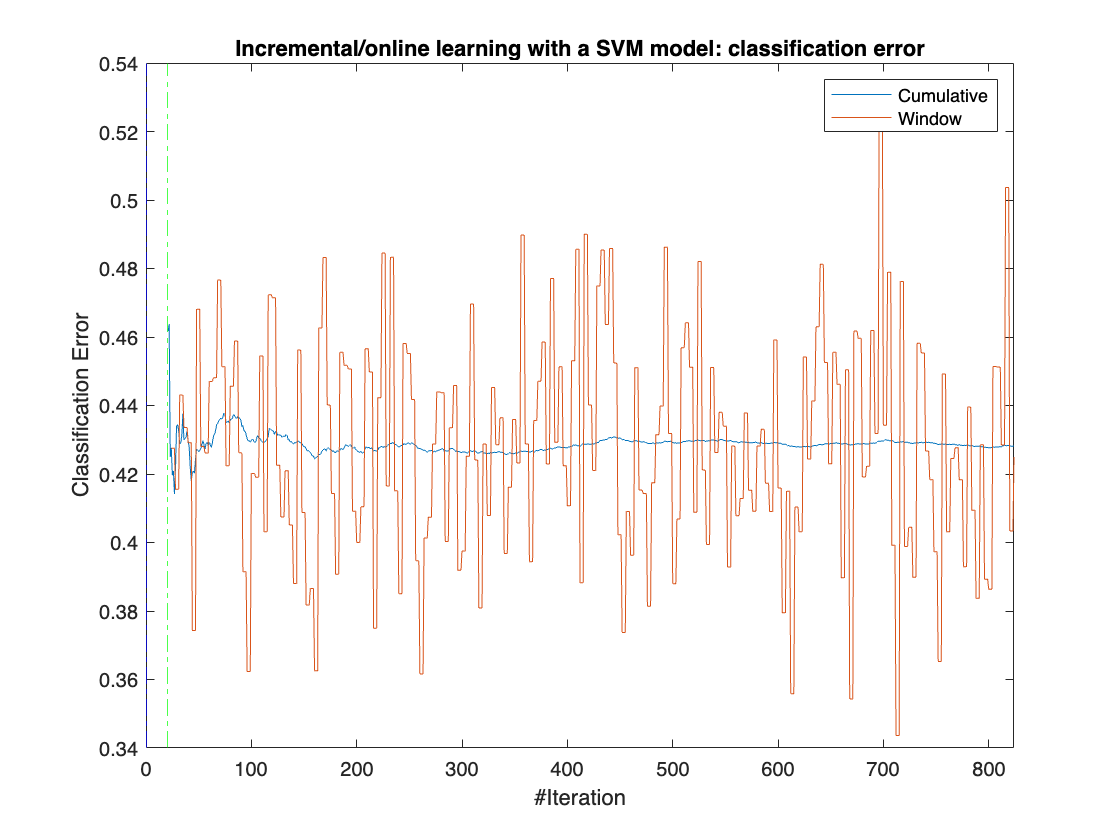

figure;
h = plot(ce.Variables);
xlim([0 nChunk]);
ylabel('Classification Error')
xline(Mdl.EstimationPeriod/Chunk,'b-.');
xline((Mdl.EstimationPeriod + Mdl.MetricsWarmupPeriod)/Chunk,'g-.');
legend(h,ce.Properties.VariableNames)
xlabel('#Iteration')
title('Incremental/online learning with a SVM model: classification error')

#### Step 3 - A new user arrives (NOTE: here the prediction is for a single nudging technique)

New user: age = 33, gender = F, education = high => User encoding: [0  0  1]

(You can insert a matrix of new users here, not just a vector.)

newUser = [0  0  1];
X = newUser;
label = predict(Mdl,X)

label = 1

### Naive Bayes

We try to use a Naive Bayes classification model for incremental learning.

The model is formally unsuitable for this problem, as it assumes that the independent variables are normally distributed. But it is instructive to see how it cope with the problem: Naive Bayes is (usually) a very robust model for violations of the underlying hypotheses, and therefore it is very useful to see it at work. It's a great baseline model.

#### Step 1 - model creation

We create a binary Naive Bayes classification model for incremental learning (we use it in binary classification fashion, but it can be used for multiclass problems). The prior distribution is based on the empirical frequencies.

Mdl = incrementalClassificationNaiveBayes('MaxNumClasses',2)

Mdl =   incrementalClassificationNaiveBayes

                    IsWarm: 0
                   Metrics: [1×2 table]
                ClassNames: [1×0 double]
            ScoreTransform: 'none'
         DistributionNames: 'normal'
    DistributionParameters: {}


  Properties, Methods


#### Step 2 - Online running (simulation) 

We simulate "live conditions", as we did before. As before, I choose the variables, that is the form of nudging (I leave it to you as an exercise to try the other two).

y = y_FR;
X = Features_FR;
Chunk = 50; % try 25, 100...
n = length(y);
nChunk = floor(n/Chunk);
mc = array2table(zeros(nChunk,2),'VariableNames',["Cumulative" "Window"]); % Misclassification error rate

% Incremental learning process
for j = 1:nChunk
    ibegin = min(n,Chunk*(j-1) + 1);
    iend   = min(n,Chunk*j);
    idx = ibegin:iend;    
    Mdl = updateMetricsAndFit(Mdl,X(idx,:),y(idx)); % check/fit/prediction
    mc{j,:} = Mdl.Metrics{"MinimalCost",:}; % store Misclassification error rate
    
end
Mdl

Mdl =   incrementalClassificationNaiveBayes

                    IsWarm: 1
                   Metrics: [1×2 table]
                ClassNames: [0 1]
            ScoreTransform: 'none'
         DistributionNames: {'normal'  'normal'  'normal'}
    DistributionParameters: {2×3 cell}


  Properties, Methods


Let's see the classification error (after the model is warmed up).

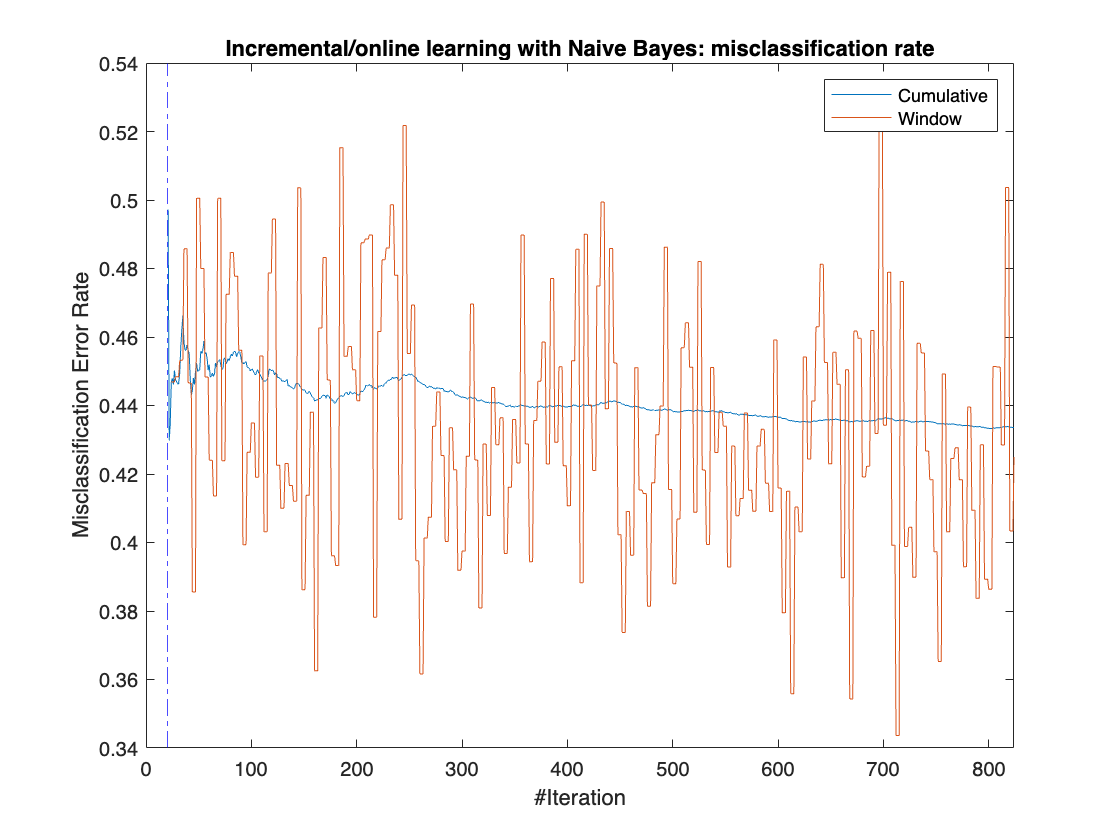

figure;
h = plot(mc.Variables);
xlim([0 nChunk]);
ylabel('Misclassification Error Rate')
xline(Mdl.MetricsWarmupPeriod/Chunk,'b-.');
legend(h,mc.Properties.VariableNames)
xlabel('#Iteration')
title('Incremental/online learning with Naive Bayes: misclassification rate')

#### Step 3 - A new user arrives (NOTE: here the prediction is for a single nudging technique)

New user: age = 33, gender = F, education = high => User encoding: [0  0  1]

We get also:

The [posterior probabilities](https://it.mathworks.com/help/stats/incrementalclassificationnaivebayes.predict.html#mw_d6e3c460-17b4-4fb0-ae2d-9334e43c042b), ie the probability that an observation belongs in a particular class, given the data;

The predicted (expected) [misclassification costs](https://it.mathworks.com/help/stats/incrementalclassificationnaivebayes.predict.html#mw_84606f22-6a3f-42ac-bd0b-67e4d99d9365) corresponding to the new observation(s) - you can insert a matrix of new users here, not just a vector - for each observation, the predicted class label corresponds to the minimum expected classification cost among all classes.

newUser = [0  0  1];
X = newUser;
[label,Posterior,Cost] = predict(Mdl,X)

label = 1

Posterior =     0.3021    0.6979


Cost =     0.6979    0.3021


## What you might do

***HINTS***:

- You can try to use the "traditional" Machine Learning approach on this data - I mean, not online learning - for example use a Neural Network, Bagging,  Boosting, etc and see the differences;

- You might also use a Multiarmed-Bandit algorithm (you win if you convince the client, you have to pick the right nudging content - the one with the highest winning probability) - it's a very simple but often powerful class of algorithms - see the course material;

- For those who do project work on recommendation systems and / or client segmentation, it may be interesting to integrate this part...